# Vision and Opponency

### Reading the Dataset

warning('off','all');
color_checker_dataset = readtable("HW_Opponency_Data.xlsx",Sheet="ColorChecker");
lms_dataset = readtable("HW_Opponency_Data.xlsx",Sheet="LMS");
light_sources_dataset = readtable("HW_Opponency_Data.xlsx",Sheet="Sources");

## Question 2

a. Calculate LMS values for all 24 ColorChecker samples, for both incandescent and daylight illumination.

%Change in Wavelength
wavelength = 380:10:730;
d_lambda = mean(diff(wavelength));

% Create LMS relative sensitivity matrix
lms_matrix = transpose(lms_dataset{:,2:4});

% calculate illuminant's spectral power distribution = S𝜆
% normalization is done to light sources to it's max value
s_incandescent = (normalize(light_sources_dataset{:,2},'range'));
s_daylight = (normalize(light_sources_dataset{:,3},'range'));


% Objectspectral reflectance factor = R𝜆 
[color_checker_numRows,color_checker_numCols] = size(color_checker_dataset);
r_matrix = color_checker_dataset{:,2:color_checker_numCols};

% LMS values for all 24 ColorChecker samples
LMS_stimuli_incandescent = LMS_stimuli(lms_matrix, ...
    diag(s_incandescent), r_matrix,d_lambda)

LMS_stimuli_incandescent =     6.1601   21.2330    8.7393    6.7169   12.0632   18.3657   20.3242    5.1711   14.8841    3.7096   21.8680   26.6102    2.4611   10.1399   10.2987   34.1237   13.9445    7.1037   47.4235   30.8011   18.5114   10.2061    4.6335    1.6968
    3.4530   12.3532    6.5834    4.9096    8.0757   15.2685   10.0784    3.9806    6.1670    2.0669   15.9962   15.1855    1.9559    8.5654    3.1995   21.2021    5.7928    6.5828   32.0226   20.9906   12.6333    7.0009    3.1819    1.1573
    0.4673    1.9159    2.3974    0.5247    3.0230    3.3093    0.4609    2.5368    0.9946    0.9316    0.9972    0.6575    2.0262    0.8070    0.3594    0.8631    2.0106    2.7934    6.6014    4.5090    2.7466    1.5152    0.6925    0.2572


LMS_stimuli_daylight = LMS_stimuli(lms_matrix, ... 
    diag(s_daylight), r_matrix, d_lambda)

LMS_stimuli_daylight =     7.9622   28.3691   14.5461   10.4358   18.3820   32.2160   23.7162    9.0313   16.2376    4.9913   33.6387   33.8575    4.5933   17.6658    9.7257   46.3934   15.6261   14.2828   70.6096   46.2115   27.8066   15.3847    6.9925    2.5511
    6.0577   22.5268   14.4775    9.5055   17.1260   32.8450   15.1642    9.5332    9.7285    4.1998   30.1597   24.4327    5.1990   17.6418    4.5954   36.6076   10.3696   16.3511   62.7903   41.3831   24.9222   13.8283    6.2939    2.2918
    3.1505   12.7636   16.7560    3.3499   21.3916   21.2245    2.8945   18.3435    6.9820    7.1588    5.3895    4.0054   14.6722    4.4367    2.4699    4.5198   14.9791   18.3518   44.5622   30.7406   18.8032   10.3664    4.7441    1.7680


2b. Compute the CATs (**M**vonKries), assuming complete chromatic adaptation to Illuminant E (also known as equal-energy illuminant, a spectral power distribution with a value of 1 at all wavelengths), for incandescent and daylight illumination.

% Equi-energy light source is Illuminant E (L2)
s_illuminantE = ones(36,1);


% LMS_lightsource
LMS_source_daylight = LMS_source(lms_matrix,s_daylight,d_lambda);
LMS_source_incandescent = LMS_source(lms_matrix,s_incandescent,d_lambda);
LMS_source_illuminantE = LMS_source(lms_matrix,s_illuminantE,d_lambda);

% LMS_source_daylight = LMS_source(lms_matrix,...
% diag(s_daylight),d_lambda);
% LMS_source_incandescent = LMS_source(lms_matrix,...
% diag(s_incandescent),d_lambda);
% LMS_source_illuminantE = LMS_source(lms_matrix,...
% diag(s_illuminantE),d_lambda);


% Computing the CAT (Von Kries M Matrix)
vonkries_incandescent = vonkries(LMS_source_incandescent,...
    LMS_source_illuminantE)

vonkries_incandescent =     2.1469         0         0
         0    2.5771         0
         0         0    8.3953


vonkries_daylight = vonkries(LMS_source_daylight,...
    LMS_source_illuminantE)

vonkries_daylight =     1.4316         0         0
         0    1.3059         0
         0         0    1.2243


% LMS values of stimuli after applying von kries matrix
LMS_stimuli_incandescent_vk = vonkries_incandescent * LMS_stimuli_incandescent;
LMS_stimuli_daylight_vk = vonkries_daylight * LMS_stimuli_daylight;


2c. Calculate opponent signals for all 24 ColorChecker samples, for both incandescent and daylight illumination using the CATs you computed. Set gamma to 2.4.

m_opponency = [0.64 0.39 -0.01; 1.12 -1.50 0.34; 0.35 0.15 -0.53];

gamma = 2.4;

opponency_incandescent = calcOpponency(m_opponency,...
    LMS_stimuli_incandescent_vk,gamma)

opponency_incandescent =     2.8288    4.7605    3.4051    3.0500    3.8264    4.7202    4.5839    2.7379    3.9211    2.2788    4.9944    5.2300    2.0132    3.7037    3.2485    5.8728    3.8084    3.2232    6.7924    5.6815    4.5962    3.5891    2.5832    1.6979
    0.1559    0.2391    0.1075   -0.2827    0.3405   -0.3923    0.1711    0.3125    0.8179    0.4484   -0.6718   -0.1772    0.4054   -0.6484    0.9946   -0.4656    1.0936   -0.1285    0.0658    0.0568    0.0491    0.0280    0.0204    0.0229
    0.4626    0.6669   -0.1760    0.5128   -0.1498    0.1933    1.3392   -0.5457    0.6740   -0.1167    1.1619    1.4997   -0.7315    0.6316    0.7931    1.6794    0.1847   -0.3961    0.5222    0.3892    0.3043    0.2381    0.1684    0.1059


opponency_daylight = calcOpponency(m_opponency,LMS_stimuli_daylight_vk,gamma)

opponency_daylight =     2.6699    4.5598    3.5598    3.0706    3.8846    4.9869    4.1163    2.9379    3.4743    2.2201    4.9960    4.8559    2.2358    3.8800    2.7245    5.6100    3.4578    3.6103    6.7731    5.6814    4.5980    3.5947    2.5885    1.6999
    0.1330    0.1730    0.0605   -0.2165    0.2251   -0.3337    0.2363    0.2074    0.6600    0.3330   -0.5574   -0.0467    0.2558   -0.5522    0.7299   -0.3863    0.7888   -0.1889    0.0561    0.0574    0.0528    0.0338    0.0243    0.0220
    0.3897    0.5857   -0.1156    0.5541   -0.1514    0.3860    1.1429   -0.4922    0.4350   -0.2104    1.2884    1.3703   -0.6654    0.8263    0.5247    1.6810   -0.0591   -0.1705    0.5309    0.3951    0.3066    0.2425    0.1716    0.1061


## Question 3

Look at the opponent signals for the ColorChecker neutral patches (19-24) as well as yellow (16). Do the values make sense, compared to what opponent signals would you expect for neutral samples? Does the CAT do what it’s supposed to?

cmp_table_daylight = array2table([opponency_daylight(:,16), opponency_daylight(:,19:24)]);
cmp_table_daylight.Properties.VariableNames = ["Pat16","Pat19","Pat20","Pat21","Pat22","Pat23","Pat24"];
cmp_table_daylight

cmp_table_daylight = 3×7 table
     Pat16       Pat19       Pat20       Pat21       Pat22       Pat23       Pat24  
    ________    ________    ________    ________    ________    ________    ________

        5.61      6.7731      5.6814       4.598      3.5947      2.5885      1.6999
    -0.38627    0.056139    0.057431    0.052781    0.033838    0.024282    0.021978
       1.681     0.53089      0.3951     0.30663     0.24247     0.17163     0.10612


cmp_table_incandescent = array2table([opponency_incandescent(:,16), opponency_incandescent(:,19:24)]);
cmp_table_incandescent.Properties.VariableNames = ["Pat16","Pat19","Pat20","Pat21","Pat22","Pat23","Pat24"];
cmp_table_incandescent

cmp_table_incandescent = 3×7 table
     Pat16       Pat19       Pat20       Pat21       Pat22      Pat23       Pat24  
    ________    ________    ________    ________    _______    ________    ________

      5.8728      6.7924      5.6815      4.5962     3.5891      2.5832      1.6979
    -0.46563    0.065781    0.056774    0.049141    0.02796    0.020433    0.022941
      1.6794     0.52216     0.38924     0.30426    0.23812     0.16843     0.10585


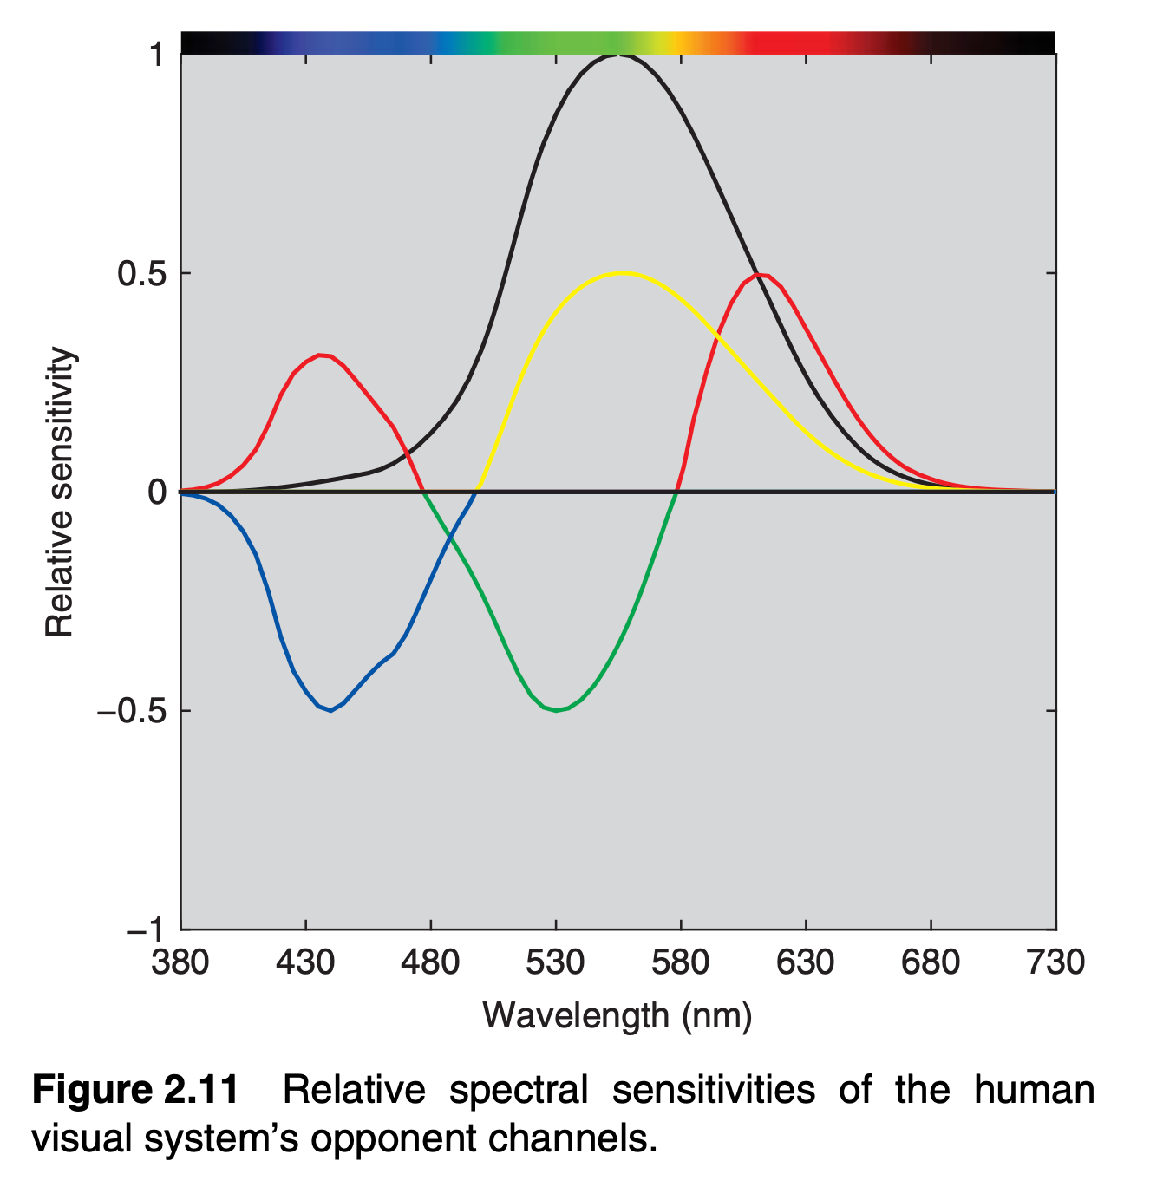				

The above graph represents “Relative spectral sensitives of the human visual system’s opponent channels.” The black curve, red-green curve, and yellow-blue curve represent the white opposed by black channel, red opposed by green channel, and yellow opposed by blue channel, respectively. 	L and M cones combine, forming the white opposed by black signal with nominal pulse rate between 0(complete black) to 1(pure weight) relative sensitivity. 

The result of the opponency signals for the given neutral patches (19-24) as well as yellow (patch 16) from the ColorChecker values make sense. The neutral patches in the ColorChecker showed a decreasing order from left to right as well as opponency signal results for both incandescent and day light sources as the colors become darker. 

To address whether the CAT did what it is supposed to do, I calculated the opponency with LMS before CATs.

opponency_incandescent_bef = calcOpponency(m_opponency,...
    LMS_stimuli_incandescent,gamma);
opponency_daylight_bef = calcOpponency(m_opponency,LMS_stimuli_daylight,gamma);

cmp_table_daylight_bef = array2table([opponency_daylight_bef(:,16), opponency_daylight_bef(:,19:24)]);
cmp_table_daylight_bef.Properties.VariableNames = ["Pat16","Pat19","Pat20","Pat21","Pat22","Pat23","Pat24"];
cmp_table_daylight_bef

cmp_table_daylight_bef = 3×7 table
     Pat16       Pat19       Pat20        Pat21        Pat22       Pat23        Pat24  
    ________    ________    ________    _________    _________    ________    _________

      4.8955      5.9118       4.959       4.0134       3.1376      2.2594       1.4838
    -0.54497    -0.16352    -0.12694    -0.096873    -0.082362    -0.05932    -0.033479
      1.4102      0.3261     0.22744      0.17201      0.13703     0.09595      0.05694



cmp_table_incandescent_bef = array2table([opponency_incandescent_bef(:,16), opponency_incandescent_bef(:,19:24)]);
cmp_table_incandescent_bef.Properties.VariableNames = ["Pat16","Pat19","Pat20","Pat21","Pat22","Pat23","Pat24"];
cmp_table_incandescent_bef

cmp_table_incandescent_bef = 3×7 table
     Pat16        Pat19       Pat20        Pat21        Pat22        Pat23        Pat24   
    ________    _________    ________    _________    _________    _________    __________

      4.1687       4.8266      4.0371        3.266       2.5503       1.8355        1.2065
    -0.15991    -0.020447    -0.02426    -0.019293    -0.022114    -0.016222    -0.0049946
      1.5605       1.2197      1.0004      0.80492      0.62864      0.45122       0.29467


Comparing the opponent values from two tables cmp_table_incandescent_bef vs cmp_table_daylight_bef (before CAT) and cmp_table_daylight vs cmp_table_daylight_bef (after CAT), the opponency value are consistent in both the illuminant only after applying CAT (which is the expected outcome). And also, the absolute opponency value computed after CAT correlates with the relative sensitivity graph of the human vision opponency channel graph shown above. So the CAT did what it is supposed to do.

## Question 1

Write Matlab code (with no loops!) to compute LMS values as in the sidebar on p20, and to compute opponent values by implementing Eqs. 2.27 and 2.28. The computation for matrix **M**vonKries is defined on p22. **M**opponency is defined on p25;

function T_stimuli = LMS_stimuli(t,s,r,d)
    T_stimuli = (t*s*r*d);
end

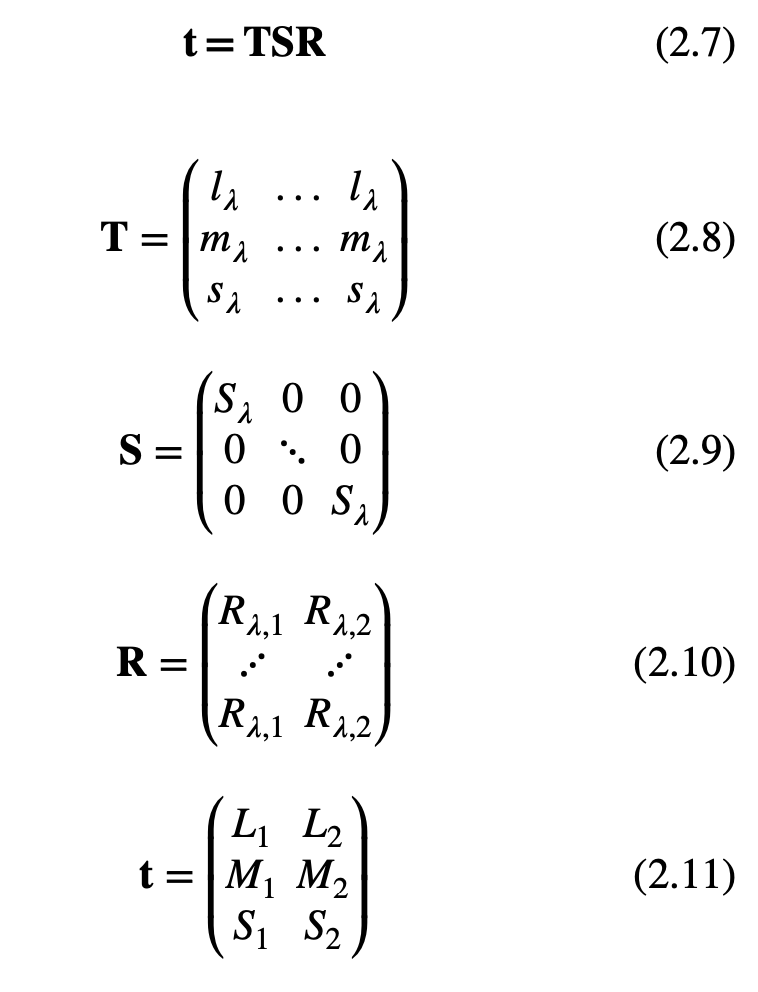

% Function to calculate Chromatic Adaptation Transformation - Von Kries
function M_factor = vonkries(LMS1,LMS2)
    M_factor = diag(LMS2./LMS1);
end



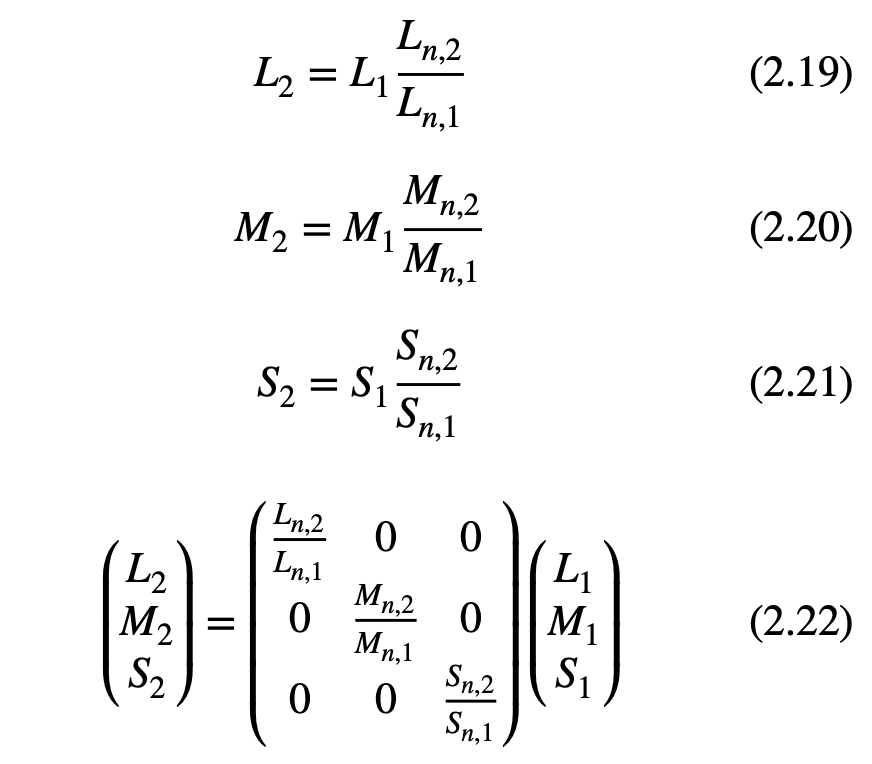

% Function to calculate Opponency
function opp = calcOpponency(m_opponency, LMS_vk, gamma)
    opp = m_opponency * ((LMS_vk).^(1/gamma));
end


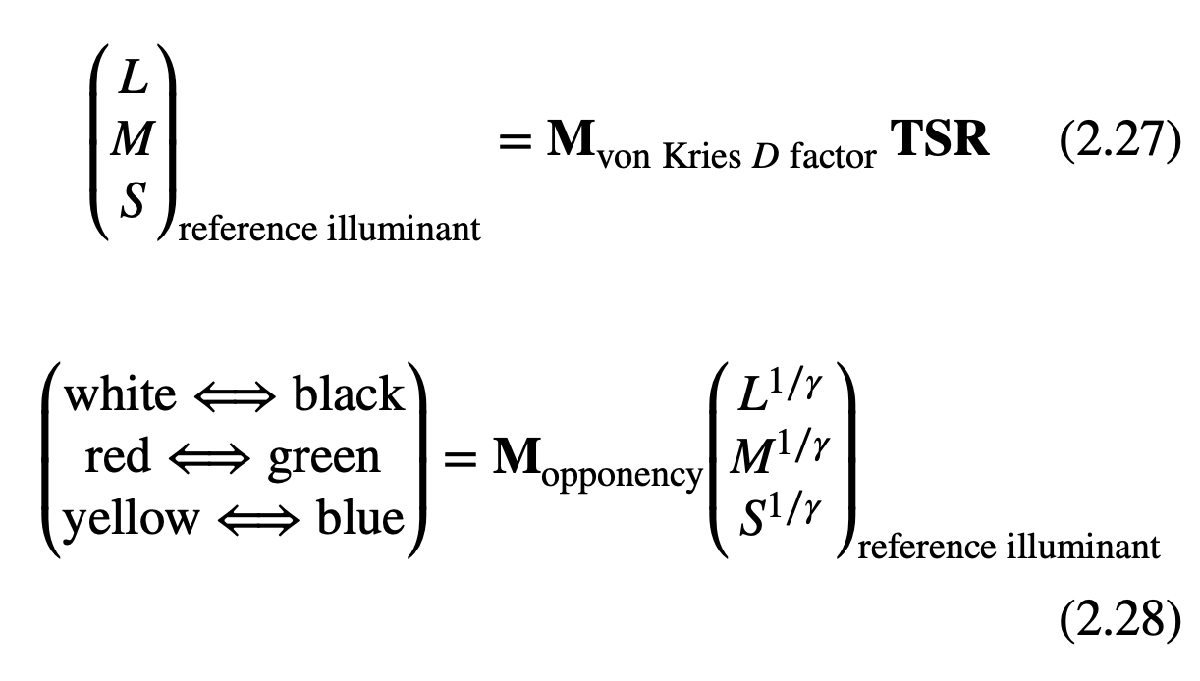

% Function to calculate LMS of the light source
function T_source = LMS_source(t,s,d)
    T_source = (t*s*d);
end